## Image Reading

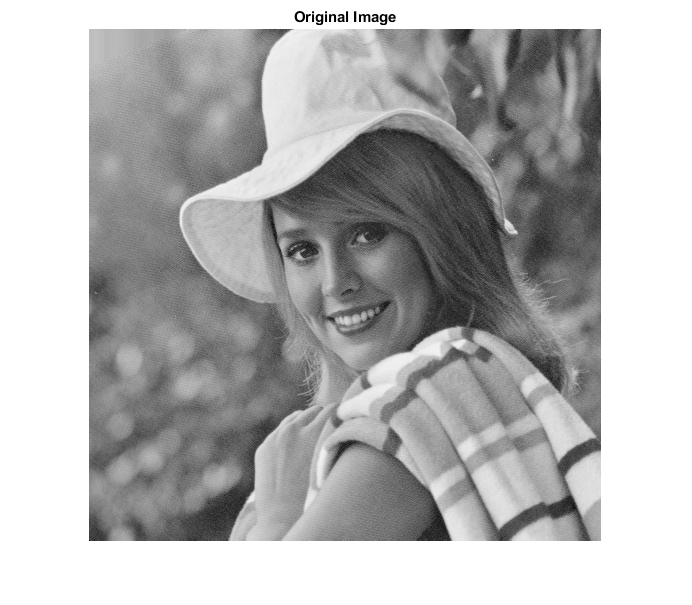

clc;
clear all; 
close all;
[file, path]=uigetfile('*.*');
I=imread(file);
figure;imshow(I);title('Original Image')

q=1;
OriginalImage=I;Q=q; 
OriginalImage=double(OriginalImage);
ImageSub=OriginalImage-128;
[Row,Col]=size(OriginalImage);
BlockNumber=Row*Col/64;

## Block Processing and applying DCT

Coef=blkproc(ImageSub,[8,8],'dct2(x)');

## Quantization Matrix

L=Q*[16  11  10  16  24  40  51  61 
     12  12  14  19  26  58  60  55 
     14  13  16  24  40  57  69  56 
     14  17  22  29  51  87  80  62 
     18  22  37  56  68 109 103  77 
     24  35  55  64  81 104 113  92 
     49  64  78  87 103 121 120 101 
     72  92  95  98 112 100 103  99];  
 
[CoefDCchanged,CoefAfterQ]=Quntization_pro(L,Row,Col,Coef,BlockNumber);

## ZigZag Scanning

ImageBitSeq=[]; 
ImageBitLen=[]; 
rowloop=0; 
for row=1:Row/8 
    colloop=0; 
    for col=1:Col/8 
       m(1:8,1:8)=CoefDCchanged((row-1)*8+1:(row-1)*8+8,(col-1)*8+1:(col-1)*8+8); 
       k= round(m);

## ZigZag Scaning

       %%********************************************************* 
       t=zigzag(k);

## Removing Extra Zeros

       %%********************************************************* 
       w=0; 
       u=64; 
       while u ~= 0 
             if t(u) ~= 0 
                w=u; 
                break; 
             end 
             u=u-1; 
       end 
       w; 
       if w==0  
          w=1; 
       end 
       e(w)=0; 
       for i=1:w 
           e(i)=t(i); 
       end 
       %e;

## Entropy Encoding with Huffman

       [blockDCbit_seq,blockDCcode_len]=DCHuffmanEncoding(e(1)); 
       blockDCbit_seq; 
       blockDCcode_len; 
       eob_seq=dec2bin(10,4);
       blockACbit_seq=[]; 
       blockbit_seq=[]; 
       zrl_seq=[]; 
       trt_seq=[]; 
       zerolen=0; 
       zeronumber=0; 
        
       if numel(e)==1 
          blockACbit_seq=[];
          blockbit_seq=[blockDCbit_seq,eob_seq]; 
          blockbit_len=length(blockbit_seq); 
       else  
          for i=2:w 
              if ( e(i)==0 & zeronumber<16) 
                  zeronumber=zeronumber+1; 
              elseif (e(i)==0 & zeronumber==16);  
                  bit_seq=dec2bin(2041,11);
                  zeronumber=1; 
                  blockACbit_seq=[blockACbit_seq,bit_seq]; 
              elseif (e(i)~=0 & zeronumber==16) 
                  zrl_seq=dec2bin(2041,11); 
                  amplitude=e(i); 
                  trt_seq=ACHuffmanEncoding(0,amplitude); 
                  bit_seq=[zrl_seq,trt_seq]; 
                  blockACbit_seq=[blockACbit_seq,bit_seq]; 
                  zeronumber=0; 
              elseif(e(i)) 
                  zerolen=zeronumber;           
                  amplitude=e(i);  
                  zeronumber=0; 
                  bit_seq=ACHuffmanEncoding(zerolen,amplitude); 
                  blockACbit_seq=[blockACbit_seq,bit_seq]; 
              end 
          end 
       end                  
       blockbit_seq=[blockDCbit_seq,blockACbit_seq,eob_seq]; 
       blockbit_len=length(blockbit_seq); 
       blockbit_seq; 
       blockbit_len; 
       ImageBitSeq=[ImageBitSeq,blockbit_seq]; 
       ImageBitLen=numel(ImageBitSeq);        
       colloop=colloop+1; 
   end 
   rowloop=rowloop+1; 
end 
ImageBitSeq; 
ImageBitLen; 
AverageBit=ImageBitLen/Row/Col;

CoefInverseQ=blkproc(CoefAfterQ,[8,8],'x.*P1',L); 
ImageSubRecon=blkproc(CoefInverseQ,[8,8],'idct2(x)'); 
ReconImage=round(ImageSubRecon)+128;
CR=Row*Col*8/ImageBitLen;
PSNR = PSNR(ReconImage,OriginalImage);

## Output Paramters

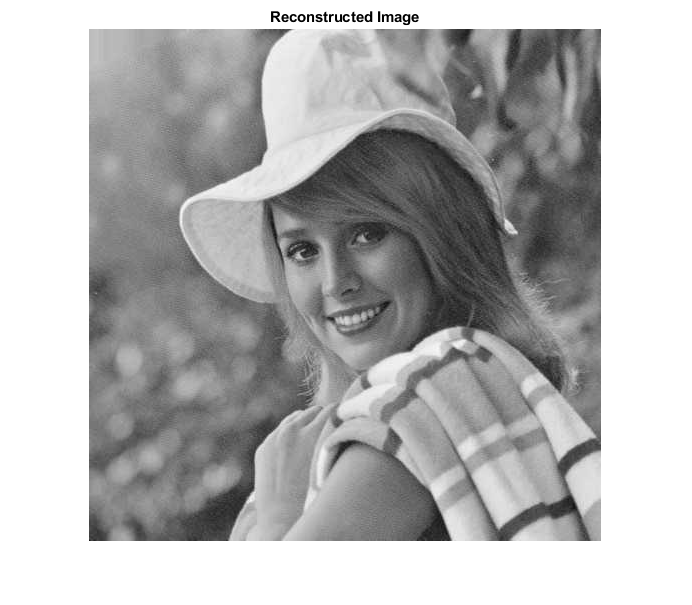

figure;imshow(uint8(ReconImage));title('Reconstructed Image')

fprintf('Compression ratio is = %f\n',ceil(CR))

Compression ratio is = 8.000000


fprintf('Peak Signal to Noise ratio is = %f\n',ceil(PSNR))

Peak Signal to Noise ratio is = 34.000000


fprintf('Average Bit per Pixel = %f\n',AverageBit)

Average Bit per Pixel = 1.020550


imwrite(uint8(ReconImage),'rec.jpg')